# Fig7 plot

## Setting up WS

CurrentFolder = pwd

CurrentFolder = '/Users/zhuochengxiao/Library/CloudStorage/OneDrive-Personal/Documents/GitHub/NYU-Vision-2Drive'

addpath(CurrentFolder)
addpath([CurrentFolder '/Utils'])
addpath([CurrentFolder '/Data'])
DataFolder = [CurrentFolder '/Data/Paper2_NetworkTuning/Fig1V4/Paper2PlotingData/']; % V1D2
DataFolder1 = [CurrentFolder '/Data/Paper2_NetworkTuning/Fig1V4/GlobConv/']; % V1D2

addpath(DataFolder1)
addpath(DataFolder)
addpath([CurrentFolder '/Data/Paper2_NetworkTuning/Fig1V4/'])

FigurePaperPath = [CurrentFolder '/Paper2Figs/']; % V1D2
DataPoint = 'V4D2'; %'V4D1'; 'V5D1'
load(sprintf("AllMFPixPara_Paper2TuneFig1%s.mat",DataPoint))

CurrentFolder = pwd

CurrentFolder = '/Users/zhuochengxiao/Library/CloudStorage/OneDrive-Personal/Documents/GitHub/NYU-Vision-2Drive'

SaveFolder = [CurrentFolder '/Data/Paper2_NetworkTuning/Fig1V4/Paper2NWSimulationData/'];
addpath(SaveFolder)

load([SaveFolder 'Paper2ConnPixel_Cconst.mat'])
close all

C_SS_mean = AveSpatKer(C_SS_Pixel_Us,N_HC,N_HC,NPixX,NPixY);
C_CS_mean = AveSpatKer(C_CS_Pixel_Us,N_HC,N_HC,NPixX,NPixY);
C_IS_mean = AveSpatKer(C_IS_Pixel_Us,N_HC,N_HC,NPixX,NPixY);
C_SC_mean = AveSpatKer(C_SC_Pixel_Us,N_HC,N_HC,NPixX,NPixY);
C_CC_mean = AveSpatKer(C_CC_Pixel_Us,N_HC,N_HC,NPixX,NPixY);
C_IC_mean = AveSpatKer(C_IC_Pixel_Us,N_HC,N_HC,NPixX,NPixY);
C_SI_mean = AveSpatKer(C_SI_Pixel_Us,N_HC,N_HC,NPixX,NPixY);
C_CI_mean = AveSpatKer(C_CI_Pixel_Us,N_HC,N_HC,NPixX,NPixY);
C_II_mean = AveSpatKer(C_II_Pixel_Us,N_HC,N_HC,NPixX,NPixY);

Load 4 angles

Fig9 = figure('Name','NW_LDE_Comp');

AngleList = {'0.0','7.5','15.0','22.5'};
DomList =  {'Small','Large'};
for AngInd = 1:4
    AngPrint = AngleList{AngInd};
    
    Small = load(sprintf('Func16%sAng%s%s.mat',DataPoint,AngPrint,DomList{1}),...
        'LDEFrfunc','L4EmeshX','L4ImeshY');
    L4EmeshX = Small.L4EmeshX;
    L4ImeshY = Small.L4ImeshY;
    LDEFrfunc = Small.LDEFrfunc;
    
    load([SaveFolder sprintf('NWSimulationPix_%sdeg_NewSmear.mat', AngPrint)])
    
    p = 1;
    LDEOut.S = LDEIterFunc_Grating_16Func(...
        L4EmeshX, L4ImeshY,...
        LDEFrfunc.S,...
        NWSmlt.L4E,NWSmlt.L4I,...
        NWSmlt.PixInptCtgrUse);
    %ORTPix,OBLPix,OPTPix,ORTOBLBd_Pix,OPTOBLBd_Pix);
    LDEOut.C = LDEIterFunc_Grating_16Func(...
        L4EmeshX, L4ImeshY,...
        LDEFrfunc.C,...
        NWSmlt.L4E,NWSmlt.L4I,...
        NWSmlt.PixInptCtgrUse);
    % ORTPix,OBLPix,OPTPix,ORTOBLBd_Pix,OPTOBLBd_Pix);
    LDEOut.I = LDEIterFunc_Grating_16Func(...
        L4EmeshX, L4ImeshY,...
        LDEFrfunc.I,...
        NWSmlt.L4E,NWSmlt.L4I,...
        NWSmlt.PixInptCtgrUse);
    %ORTPix,OBLPix,OPTPix,ORTOBLBd_Pix,OPTOBLBd_Pix);
    LDENext = struct(...
        'S',LDEOut.S*p + NWSmlt.FS*(1-p),...
        'C',LDEOut.C*p + NWSmlt.FC*(1-p),...
        'I',LDEOut.I*p + NWSmlt.FI*(1-p));
    
%     N_HCOut = 3;
%     [PreTest,~,~,~,~] = ...
%             LDEIteration_16FuncMain(...
%             PixInptCtgrUse,LDENext,p,100,...
%             C_SS_mean,C_CS_mean,C_IS_mean,...
%             C_SC_mean,C_CC_mean,C_IC_mean,...
%             C_SI_mean,C_CI_mean,C_II_mean,...
%             L4EmeshX,L4ImeshY,LDEFrfunc,...
%             N_HCOut,NPixX,NPixY,true)  ;

    Scatter plots

    sz = 10;
    subplot 121
    hold on
    scatter(NWSmlt.FS*(1-CplxR) + NWSmlt.FC*CplxR,...
          ...%  PreTest{end}.S*(1-CplxR) + PreTest{end}.C*CplxR,sz,'r.')
           InhKill(LDENext.S*(1-CplxR) + LDENext.C*CplxR, 50, [200 150], 200, 0),sz,'r.')
    NW_E = NWSmlt.FS*(1-CplxR) + NWSmlt.FC*CplxR;
    LDE_E = InhKill(LDENext.S*(1-CplxR) + LDENext.C*CplxR, 50, [200 150], 200, 0);
    Exceed_E = sum(LDE_E./NW_E>1.25)/length(NW_E)
    subplot 122
    hold on
    % scatter(NWSmlt.FI, PreTest{end}.I ,sz,[0.3010 0.3 0.9330],'.')
     scatter(NWSmlt.FI, InhKill(LDENext.I,70,[100,95], 120, 0.9) ,sz,[0.3010 0.3 0.9330],'.')
     NW_I = NWSmlt.FI;
    LDE_I = InhKill(LDENext.I,70,[100,95], 120, 0.9);
    Exceed_I = sum(LDE_I./NW_I>1.25)/length(NW_I)
end

Exceed_E = 0.3733

Exceed_I = 0.1978

Exceed_E = 0.3533

Exceed_I = 0.2044

Exceed_E = 0.3556

Exceed_I = 0.2278

Exceed_E = 0.3600

Exceed_I = 0.2056

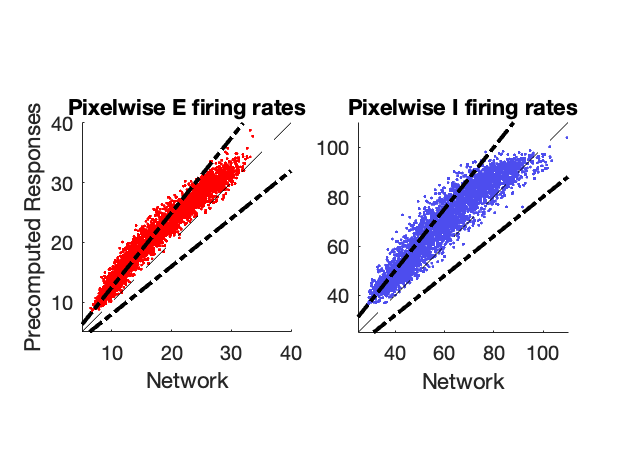


subplot 121
plot(1:100,1:100,'k--')
plot(1:100, 1.25*(1:100),'k-.','LineWidth',2)
plot(1:100, 4/5*(1:100),'k-.','LineWidth',2)
xlabel('Network')
ylabel('Precomputed Responses')
title('Pixelwise E firing rates')
axis square
axis([5 40 5 40])

subplot 122
plot(1:110,1:110,'k--')
plot(1:110, 1.25*(1:110),'k-.','LineWidth',2)
plot(1:110, 4/5*(1:110),'k-.','LineWidth',2)
xlabel('Network')
%ylabel('Responses from precomputed functions')
title('Pixelwise I firing rates')
axis square
axis([25 110 25 110])